# Дубинка подброшенная в воздух

### Пример решение системы ДУ в MATLAB с помощью не адаптивного решателя.

Составим и решим систему ДУ относительно координат массы $m_1$$\left(x_1 ,y_1 \right)$ и массы $m_2$$\left(x_2 ,y_2 \right)$.

Найдем систему ДУ в формулировках Лагранжевой механики


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}\frac{\mathrm{d}}{\mathrm{d}q^{\prime } }L\left(t,q,q^{\prime } \right)-\frac{\mathrm{d}}{\mathrm{d}q}L\left(t,q,q^{\prime } \right)=0\;\;\;\left(1\right)\\
\mathrm{где}\;q_1 =\left(x_1 ,y_1 \right),q_2 =\left(x_2 ,y_2 \right)\ldotp 
\end{array}$$


Запишем выражение для кинетической энергии первой и второй массы: $E_{1}=\frac{{V_{1}}^2\,m_{1}}{2}, E_{2}=\frac{{V_{2}}^2\,m_{2}}{2};$

и выражения для потенциальной энергии певой и второй массы: $U_{1}=g\,h_{1}\,m_{1}$, $U_{2}=g\,h_{2}\,m_{2}$.

Запишем выражения для скоростей первой и второй массы: $q'_{1} = V_{1}=\sqrt{{\left(\frac{\partial }{\partial t} x_{1}\left(t\right)\right)}^2+{\left(\frac{\partial }{\partial t} y_{1}\left(t\right)\right)}^2$, $q'_{2} = V_{2}=\sqrt{{\left(\frac{\partial }{\partial t} x_{2}\left(t\right)\right)}^2+{\left(\frac{\partial }{\partial t} y_{2}\left(t\right)\right)}^2$.

Ограничивающее выражение: $C=u\left(t\right)\,\left(m_{1}+m_{2}\right)\,\left({\left(x_{1}\left(t\right)-x_{2}\left(t\right)\right)}^2-l^2+{\left(y_{1}\left(t\right)-y_{2}\left(t\right)\right)}^2\right)$;

где: $l$ - длинна дубинки.

syms E1 E2 U1 U2 M V1 V2 g h1 h2 m1 m2
eqnE1 = E1 == 1/2*m1*V1^2; % кинетическая энергия массы 1
eqnE2 = E2 == 1/2*m2*V2^2; % кинетическая энергия массы 2
eqnU1 = U1 == m1*g*h1; % потенциальная энергия массы 1
eqnU2 = U2 == m2*g*h2; % потенциальная энергия массы 2
syms T U C x1(t) y1(t) x2(t) y2(t) u(t) l
eqnV1 = V1 == sqrt((diff(x1,t))^2+(diff(y1,t))^2); % скорость массы 1
eqnV2 = V2 == sqrt((diff(x2,t))^2+(diff(y2,t))^2); % скорость массы 2
eqnC = C == (m1+m2)*u*((x2-x1)^2+(y2-y1)^2-l^2); % выражение для функции Лагранжа
eqnT = T == rhs(eqnE1) + rhs(eqnE2);
eqnT = subs(eqnT,[V1 V2],[rhs(eqnV1) rhs(eqnV2)]); % итоговая кинетическая энергия системы
eqnU = U == rhs(eqnU1) + rhs(eqnU2);
eqnU = subs(eqnU,[h1 h2],[y1 y2]); % итоговая потенциальная энергия системы

Найдем выражение $L\left(t,q,q^{\prime } \right)$.

syms L
eqnL = L == T - U + C;
eqnL = subs(eqnL,[T U C],[rhs(eqnT) rhs(eqnU) rhs(eqnC)])  % функция Лагранжа

$$eqnL = L=\frac{m_{1}\,\left({\left(\frac{\partial }{\partial t}x_{1}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y_{1}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{2}\,\left({\left(\frac{\partial }{\partial t}x_{2}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y_{2}\left(t\right)\right)}^{2}\right)}{2}-g\,m_{1}\,y_{1}\left(t\right)-g\,m_{2}\,y_{2}\left(t\right)+u\left(t\right)\,\left(m_{1}+m_{2}\right)\,\left({\left(x_{1}\left(t\right)-x_{2}\left(t\right)\right)}^{2}-l^{2}+{\left(y_{1}\left(t\right)-y_{2}\left(t\right)\right)}^{2}\right)$$

Найдем уравнения движения дубинки подставив функцию Лагранжа в выражение $\left(1\right)$:

eqns = functionalDerivative(-rhs(eqnL),[x1 y1 x2 y2]); % минимизируем функционал
eqn5 = (x2-x1)^2 + (y2-y1)^2; % уравнение ограничивающее расстояние между массами
eqns = [eqns; eqn5] == [0; 0; 0; 0; l^2] % итоговая система

$$eqns(t) = \begin{array}{l} \left(\begin{array}{c} m_{1}\,\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)-\sigma_{8}+\sigma_{7}-\sigma_{6}+\sigma_{5}=0\\ m_{1}\,\frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)+g\,m_{1}-\sigma_{4}+\sigma_{3}-\sigma_{2}+\sigma_{1}=0\\ m_{2}\,\frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)+\sigma_{8}-\sigma_{7}+\sigma_{6}-\sigma_{5}=0\\ m_{2}\,\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)+g\,m_{2}+\sigma_{4}-\sigma_{3}+\sigma_{2}-\sigma_{1}=0\\ {\left(x_{1}\left(t\right)-x_{2}\left(t\right)\right)}^{2}+{\left(y_{1}\left(t\right)-y_{2}\left(t\right)\right)}^{2}=l^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,m_{2}\,u\left(t\right)\,y_{2}\left(t\right)\\ \sigma_{2}=2\,m_{2}\,u\left(t\right)\,y_{1}\left(t\right)\\ \sigma_{3}=2\,m_{1}\,u\left(t\right)\,y_{2}\left(t\right)\\ \sigma_{4}=2\,m_{1}\,u\left(t\right)\,y_{1}\left(t\right)\\ \sigma_{5}=2\,m_{2}\,u\left(t\right)\,x_{2}\left(t\right)\\ \sigma_{6}=2\,m_{2}\,u\left(t\right)\,x_{1}\left(t\right)\\ \sigma_{7}=2\,m_{1}\,u\left(t\right)\,x_{2}\left(t\right)\\ \sigma_{8}=2\,m_{1}\,u\left(t\right)\,x_{1}\left(t\right) \end{array}$$

vars = [x1(t); y1(t); x2(t); y2(t); u(t)]; % переменные

#### Решим систему уравнений

Для этого требуется составить пользовательскую функцию, пригодную для выбранного решателя, а так же начальные условия.

Чтобы составить пользовательскую функцию, произведем следующий алгоритм:

[eqnsR,varsR] = reduceDifferentialOrder(eqns,vars); % найдем эквивалентную систему первого порядка
[ODEs,constraints] = reduceDAEToODE(eqnsR,varsR); % конвертируем систему первого порядка в такую систему, чтобы Якобиан был обратным
[massM,f] = massMatrixForm(ODEs,varsR); % найдем массовую матрицу M и систему F, такие чтобы выполнялось условие: M(t,x(t))*x(t)'==F(t,x(t))
Lvars = length(varsR); % сосчитаем количество неизвестных
F = massM\f; % итоговая функция вида x(t)'== M(t,x(t))/F(t,x(t))
Mode = odeFunction(massM, varsR, m1, m2); % пользовательская функция для массовой матрицы
Fode = odeFunction(F, varsR, g, m1, m2); % пользовательская функция системы

Подставим численные значения в пользовательские функции:

init_cond % загрузим параметры
ODEsNumeric = subs(ODEs); % подставим численные  значения в систему первого порядка
constraintsNumeric = subs(constraints); % подставим численные  значения в ограничения
Mode = @(t,Y) Mode(t,Y,m1,m2); % пользовательская функция для массовой матрицы с численными значениями
Fode = @(t,Y) Fode(t,Y,g,m1,m2); % пользовательская функция системы с численными значениями

Найдем начальные условия для системы первого порядка

L_CM = (m1*0+m2*l)/Msum; % центр масс дубинки
x01 = 1;        y01 = 1;        % начальное положение массы 1
x02 = x01+l;    y02 = y01;      % начальное положение массы 2 
vx01 = vx0;   vy01 = -omega*L_CM+vy0; % начальная скорость массы 1
vx02 = vx0;   vy02 = omega*(l-L_CM)+vy0; % начальная скорость массы 2
y0est = [x01; y01; x02; y02; 0; vx01; vy01; vx02; vy02]; % вектор начальных значений
yp0est = zeros(Lvars,1); % предположение о начальных значениях производных 
t0 = 0;
opt1 = odeset('Mass', Mode); % настройки поиска начальных условий
[y0, yp0] = decic(ODEsNumeric, varsR, constraintsNumeric, t0,...
                y0est, [1,1,1,0,0,1,1,0,1], yp0est, opt1); % поиск начальных условий и соответствующих производных

Зададим промежуток времени и решим систему решателем c фиксированным шагом ode5 (метод Дормана-Принса)

t = t0:0.01:tend; % промежуток времени
Sol = ode5(Fode,t,y0); % решение

#### Результаты

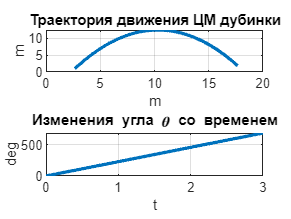

X1 = Sol(:,1); % координаты X массы 1
Y1 = Sol(:,2); % координаты Y массы 1
X2 = Sol(:,3); % координаты X массы 2
Y2 = Sol(:,4); % координаты Y массы 2
Th = unwrap(atan2((Y2-Y1),(X2-X1))); % угол вращения дубинки
X = X1+L_CM*cos(Th); % координата X ЦМ
Y = Y1+L_CM*sin(Th); % координата Y ЦМ
figure
subplot(2,1,1)
plot(X,Y,'LineWidth',2)
grid on
title('Траектория движения ЦМ дубинки')
xlabel('m')
ylabel('m')
subplot(2,1,2)
plot(t,rad2deg(Th),'LineWidth',2)
grid on
title('Изменения угла \theta со временем')
xlabel('t')
ylabel('deg')

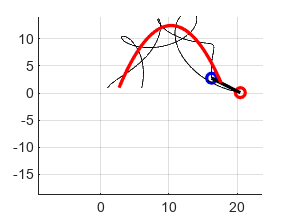

animateBaton(t,X1,Y1,X2,Y2,X,Y)

Сохраним результаты

Xart2 = X'; Yart2 = Y'; Thart2 = Th';
save('ArticlePart2Result','Xart2','Yart2','Thart2')

function animateBaton(t,X1,Y1,X2,Y2,XCM,YCM)

figure
A1 = axes;
        A1.XLim = [-10 30];
        A1.YLim = [-20 20];
grid on
Mass1 = line([0 0],[0 0],'Color','b','LineWidth',2,'Marker','o');
Mass2 = line([0 0],[0 0],'Color','r','LineWidth',2,'Marker','o');
Line_1 = line([0 0],[0 0],'Color','k','LineWidth',2);

a1 = animatedline;
a2 = animatedline;
a3 = animatedline('Color','r','LineWidth',2);
for i = 1:length(t)
    Mass1.XData = X1(i);
    Mass1.YData = Y1(i);
    Mass2.XData = X2(i);
    Mass2.YData = Y2(i);
    Line_1.XData = [X1(i) X2(i)];
    Line_1.YData = [Y1(i) Y2(i)];
    addpoints(a1,X1(i),Y1(i));
    addpoints(a2,X2(i),Y2(i));
    addpoints(a3,XCM(i),YCM(i));
    drawnow limitrate
    pause(0.1)
end
end